# Math 340: Chapter 6 Part 2 

# Amelia Rotondo, CWID: 887925113

## Question 9: 


$$\[ \int_{0}^{4\pi} cos^2(x) \,dx \]$$
 

#### Exact Solution, quadtx (wrong) solution, quad (right) solution

% Establish Data
f = @(x) (cos(x)).^2;
a = 0; b = 4*pi;
xx = a:0.1:b;

% Different Solutions 
q_exact = integral(f, a, b);
q_tx = quadtx(f, a, b);
q_quad = quad(f, a, b);

% Compare Solutions
fprintf('Exact Integral : %.9f\nQuadTX Integral: %.9f\nQuad Integral  : %.9f\n', q_exact, (q_tx), (q_quad));

Exact Integral : 6.283185307
QuadTX Integral: 12.566370614
Quad Integral  : 6.283185278


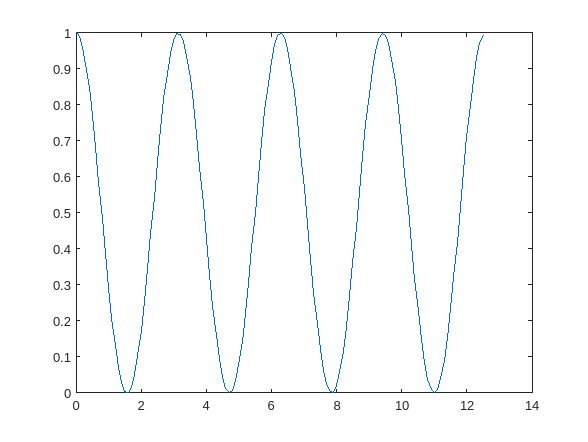

plot(xx, f(xx));

QuadTX is returning a value that appears to be twice the value of Quad. Through debugging with quadgui, it's clear that QuadTX is not using enough points to get a well-represented approximation of the integral. By evaluating only the peaks of the function, it fails to consider the oscillating movement of the graph, and evaluates it as if it were a straight line. Quad improves on this by using a better variety of initial points so that these recursive dead-ends can be avoided.  

## Question 11:


$$\[ \int_{0}^{1} x^x \,dx \]$$


#### plot the symbolic func, try to integrate, analyze the error in the result.

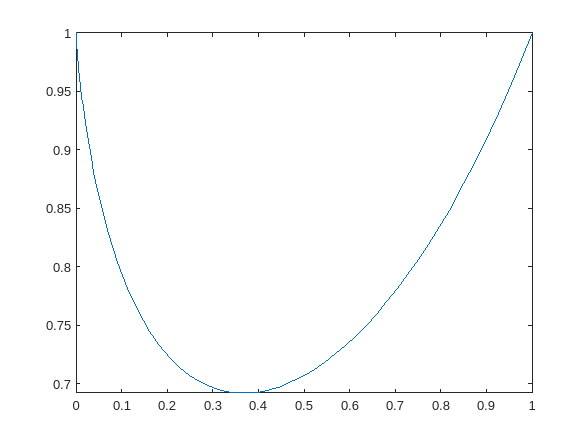

% Initial Data 
f = @(x)x.^x;
a = 0; b = 1; 
d = [a, b];

% Symbolic Representation
syms x(x); 
f_sym = x.^x;
fplot(f_sym, d);


% Integration 
q_exact = integral(f, a, b);
[q_quad, s_quad] = quad(f, a, b, 1e-9);
fprintf('Exact Integral: %.9f\nQuad Integral : %.9f\nDiff Between : %.9f\nQuad Steps: %d\n', q_exact, q_quad, (q_exact-q_quad), s_quad);

Exact Integral: 0.783430511
Quad Integral : 0.783430512
Diff Between : -0.000000001
Quad Steps: 129


When Integrating this function by hand, it appears to chain infinitely, and therefore no elementary antiderivative exists. While both Integral and Quad can assess this function up to a given tolerance, this is only through the recursive numerical integration, and therefore will always possess some margin of error from the theoretical nonexistent elementary antiderivative. 

## Question 14:

#### 
$$\[ \int_{-1}^{2} \frac{1}{sin(\sqrt{(|t|}) \,dt \]$$


#### evaluate with quadtx, analyze why t = 0 does not throw errors.

% Initial Data 
f = @(t)1./(sin(sqrt(abs(t))));
a = -1; b = 2; 
d = [a, b];
xx = a:0.1:b;

% Evaluate 
q_tx = quadtx(f, a, b);
fprintf('QuadTX Integral: %.9f\n', q_tx);

QuadTX Integral: 5.314113894


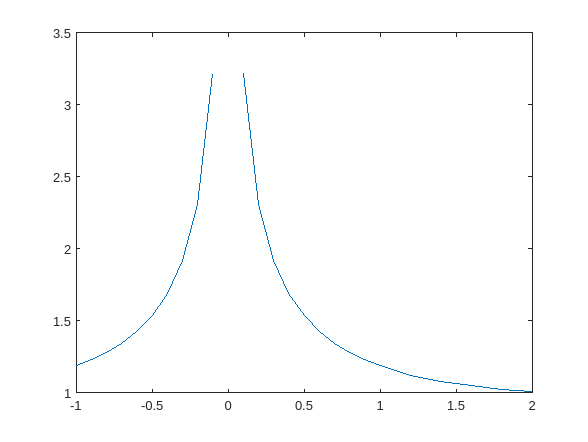

plot(xx, f(xx));

t = 0 does not throw any errors because as shown in the graph, as t approaches 0, f(0) approaches infinity. Since it only evaluates to a given tolerance, it does not attempt to infinitely approximate, instead opting to divide the infinite segment into only a necessary amount of components to achieve this tolerance. 

## Question 15:


$$\[ \int_{a}^{b} f(x) \,dt \]$$


#### modify quadtx to detect and adjust for infinite values of a and b. 

% LINES ADDED TO QUADTX:
%{
if a == -Inf || b == Inf
    disp('Infinite Bounds Detected, Adjusting Bounds Accordingly');
    if a == -Inf
        a = -1e6;
    end
    if b == Inf
        b = 1e6;
    end
end 

if abs(Q2 - Q1) <= tol
   if a == -1e6
       mod = F(-9e99);
   elseif b == 1e6
       mod = F(9e99);       
   end
    Q  = (Q2 + (Q2 - Q1)/15) + mod;
    fcount = 2;
%}

% Showcasing the Implemented Changes
f = @(x)x.^2;
a = -Inf; b = 0;
disp(quadtx(f, a, b));

Infinite Bounds Detected, Adjusting Bounds Accordingly
  8.1000e+199



To modify QuadTX to handle infinite values, I've added parameters to reroute the infinite values to the bounds of -1000000 or 1000000 respectively. At the end of the approximation, it adds the value of F(-9e99) or F(9e99) to respectively determine the long term behaviors of the function.  

## Question 23:

#### Calculate the Area of a Hand:

a. Use the Area of a Polygon with the One Liner: 

%{
    (x’*y([2:n 1]) - x([2:n 1])’*y)/2
%}

b. Use `inpolygon` with a `meshgrid` to Approximate by checking what gridded area is within the polygonal region:

%{
    [u,v] = meshgrid(xmin:h:xmax,ymin:h:ymax)
    k = inpolygon(u,v,x,y)
    hˆ2*nnz(k)
%}

c.  Use Adaptive Quadrature with `dblquad and chi.m `to find the area of the polygon as a double-integral: 


$$\int\int X(u,v) dudv$$


%{
    function k = chi(u,v,x,y)
    if all(size(u) == 1), u = u(ones(size(v))); end
    if all(size(v) == 1), v = v(ones(size(u))); end
    k = inpolygon(u,v,x,y);

    dblquad(@chi,xmin,xmax,ymin,ymax,tol,[],x,y)
%}